omega_p = 1.5708

omega_p = 1.5708

omega_s = 1.7203

omega_s = 1.7203

Delta_p = 0.05

Delta_p = 0.0500

Delta_s = 0.05

Delta_s = 0.0500


M_val = 56

M_val = 56

omega_c_val = linspace(omega_p, omega_s, 1000);
beta_val = 1.6:0.01:1.65;

best_filters = cell(1, 3);
best_p = [0.05 0.05 0.05];
best_s = [0.05 0.05 0.05];
ord = [100 100 100]

ord =    100   100   100


oc = zeros(1,3);
b = zeros(1,3);

for i = 1:length(M_val)
    for j = 1:length(omega_c_val)
        for k = 1:length(beta_val)
            M = M_val(i);
            omega_c = omega_c_val(j);
            beta = beta_val(k);
            win = kaiser(M,beta);
                
            h = fir1(M-1, omega_c / pi, win);
    
            [Delta_pr,Delta_sr] = PS_PRJ_1_Faza_3a(h,omega_p,omega_s);
    
            if Delta_pr <= best_p(1,1) && Delta_sr <= best_s(1,1) && M <= ord(1)
                best_filters{1, 1} = h;
                best_p(1, 1) = Delta_pr;
                best_s(1, 1) = Delta_sr;
                ord(1) = M;
                oc(1) = omega_c;
                b(1) = beta;
            elseif Delta_pr <= best_p(1,2) && Delta_sr <= best_s(1,2) && M <= ord(2)
                best_filters{1, 2} = h;
                best_p(1, 2) = Delta_pr;
                best_s(1, 2) = Delta_sr;
                ord(2) = M;
                oc(2) = omega_c;
                b(2) = beta;
            elseif Delta_pr <= best_p(1,3) && Delta_sr <= best_s(1,3) && M <= ord(3)
                best_filters{1, 3} = h;
                best_p(1, 3) = Delta_pr;
                best_s(1, 3) = Delta_sr;
                ord(3) = M;
                oc(3) = omega_c;
                b(3) = beta; 
            end
        end
    end
end

for i = 1:3
    disp(['M = ' num2str(ord(i)) ', omega_c = ' num2str(oc(i)) ...
    ', Delta_pr = ' num2str(best_p(1, i)) ', Delta_sr = ' num2str(best_s(1, i)) ', beta = ' num2str(b(i))]);
end

M = 56, omega_c = 1.6479, Delta_pr = 0.038168, Delta_sr = 0.04478, beta = 1.63
M = 56, omega_c = 1.648, Delta_pr = 0.038164, Delta_sr = 0.044814, beta = 1.63
M = 56, omega_c = 1.6476, Delta_pr = 0.038929, Delta_sr = 0.044852, beta = 1.63



best_tol = [best_p(1,1)+best_s(1,1) best_p(1,2)+best_s(1,2) best_p(1,3)+best_s(1,3)]

best_tol =     0.0829    0.0830    0.0838


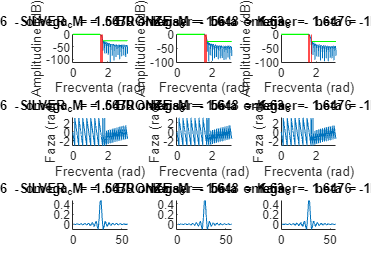

h = cell2mat(best_filters(1,1));
omega_c = oc(1);

[H1,w1] = freqz(cell2mat(best_filters(1,1)),1,5000);
[H2,w2] = freqz(cell2mat(best_filters(1,2)),1,5000);
[H3,w3] = freqz(cell2mat(best_filters(1,3)),1,5000);

tp = linspace(0,omega_p,5000);
ts = linspace(omega_s,pi,5000);
xpp = mag2db(1+Delta_p)*ones(size(tp));
xpm = mag2db(1-Delta_p)*ones(size(tp));
xs = mag2db(Delta_s)*ones(size(ts));

%Figura 19
figure;
subplot(3,3,1);
hold on;
plot(w1,mag2db(abs(H1)));
xline([omega_p oc(1) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("GOLD M = 56 - omega_c = 1.6479 - Kaiser - beta = 1.63");
hold off;

subplot(3,3,2);
hold on;
plot(w2,mag2db(abs(H2)));
xline([omega_p oc(2) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("SILVER M = 56 - omega_c = 1.648 - Kaiser - beta = 1.63");
hold off;

subplot(3,3,3);
hold on;
plot(w3,mag2db(abs(H3)));
xline([omega_p oc(3) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("BRONZE M = 56 - omega_c = 1.6476 - Kaiser - beta = 1.63");
hold off;

subplot(3,3,4);
hold on;
plot(w1,angle(H1));
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("GOLD M = 56 - omega_c = 1.6479 - Kaiser - beta = 1.63");
hold off;

subplot(3,3,5);
hold on;
plot(w2,angle(H2));
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("SILVER M = 56 - omega_c = 1.648 - Kaiser - beta = 1.63");
hold off;

subplot(3,3,6);
hold on;
plot(w3,angle(H3));
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("BRONZE M = 56 - omega_c = 1.6476 - Kaiser - beta = 1.63");
hold off;

subplot(3,3,7);
hold on;
plot(cell2mat(best_filters(1,1)));
title("GOLD M = 56 - omega_c = 1.6479 - Kaiser - beta = 1.63");
hold off;

subplot(3,3,8);
hold on;
plot(cell2mat(best_filters(1,2)));
title("SILVER M = 56 - omega_c = 1.648 - Kaiser - beta = 1.63");
hold off;

subplot(3,3,9);
hold on;
plot(cell2mat(best_filters(1,3)));
title("BRONZE M = 56 - omega_c = 1.6476 - Kaiser - beta = 1.63");
hold off;

function [Delta_pr,Delta_sr] = PS_PRJ_1_Faza_3a(h,omega_p,omega_s)
    [H, omega] = freqz(h, 1, 1000);

    omega_p_idx = find(omega <= omega_p);
    omega_s_idx = find(omega >= omega_s);

    H_p = abs(H(omega_p_idx));
    H_s = abs(H(omega_s_idx));

    Delta_pr = max(abs(1-H_p));
    Delta_sr = max(H_s);
end
